# Spike detection

Simulating the signal

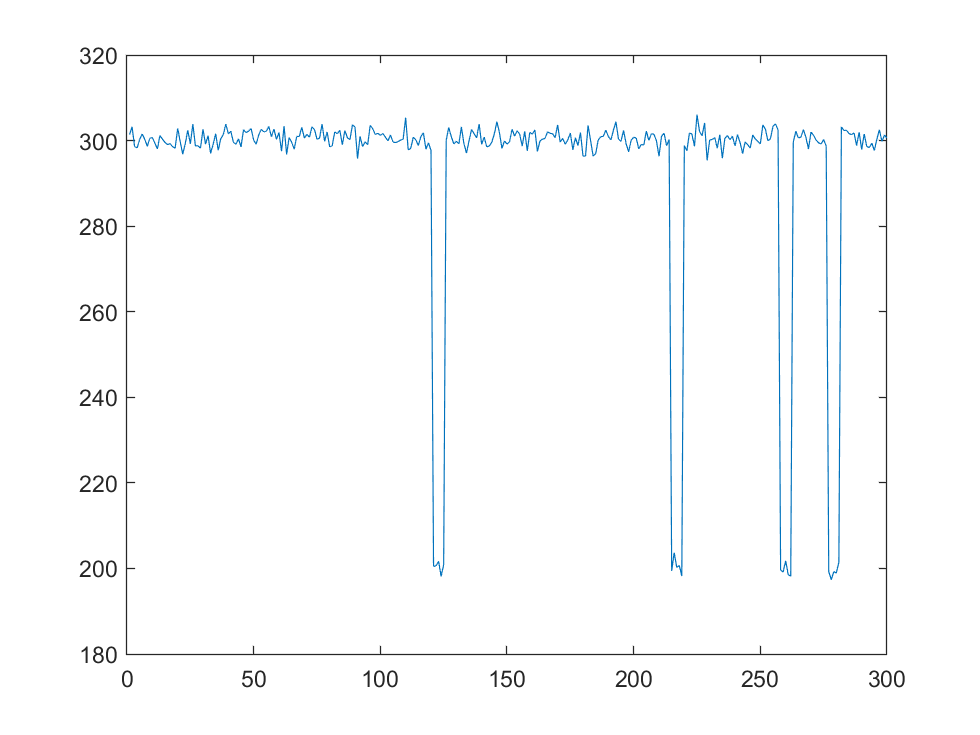

N = 300;
% s = 10*rand(N,1) + 100;
% spikeIndices = randi(N, [20, 1]);
% s(spikeIndices) = s(spikeIndices) - 50;
tAll = (1:N).';
s = 300 + 0.3*tAll.^(0) + 2*randn(N,1);

spikeIndices = randi(N, [4, 1]);
spikeIndices = [spikeIndices; spikeIndices+1; spikeIndices+2;...
    spikeIndices+3; spikeIndices+4];
s(spikeIndices) = s(spikeIndices) - 100;
S = CircArray(s);
plot(s)


dt = 0.2 % seconds

dt = 0.2000

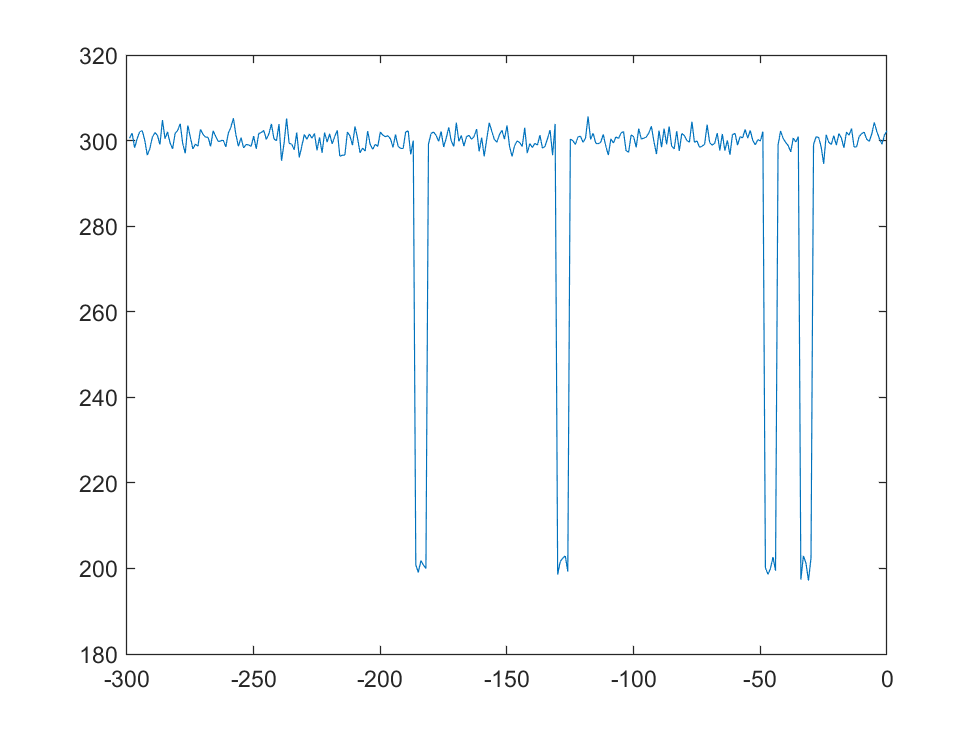

S.RunningPlot(N)

S

S =   CircArray with properties:

          Data: [300×1 double]
        Length: 300
    CurrentPos: 0


% for tt = (0:2*pi/N:2*pi)
%     newInput = 300 + 100*sin(10*tt);
%     S.WriteVals(1, newInput);
%     S.RunningPlot(50)
%     drawnow;
%     pause(0.1)
% end

Threshold-based detection

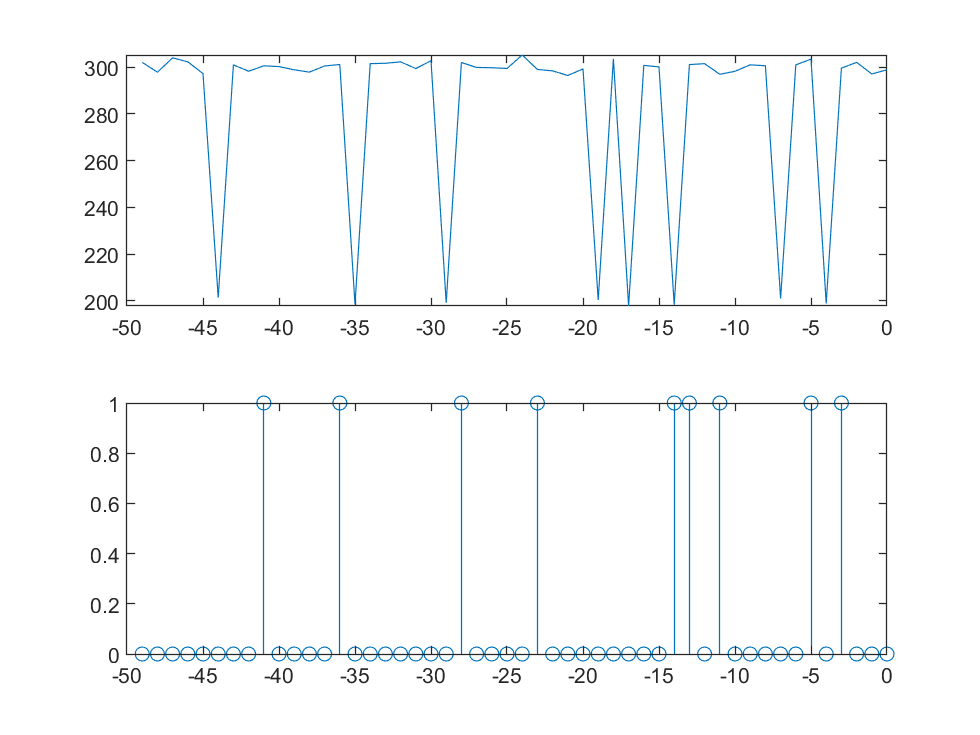

thresholdVal = 220; % Change to Volts
numConsecVals = 1;
trackBlinks = CircArray(zeros(N,1));
counter = 0;
figure;
tic;
while (toc<30)
    tNow = toc;
    newInput = 300 + 0.3*tNow.^(0) + 2*randn(1) - 100*(rand(1)>0.9);
    S.WriteVals(1, newInput);
    subplot(2,1,1)
    S.RunningPlot(50)
    
    
    if S.GetVals(0) < thresholdVal
        counter = counter + 1;
        trackBlinks.WriteVals(1,0)
    else
        if counter >= numConsecVals
            trackBlinks.WriteVals(1,1);
        else
            trackBlinks.WriteVals(1,0);
        end
        counter = 0;
    end
    subplot(2,1,2)
    trackBlinks.RunningStem(50)
    drawnow;
    pause(dt)
end

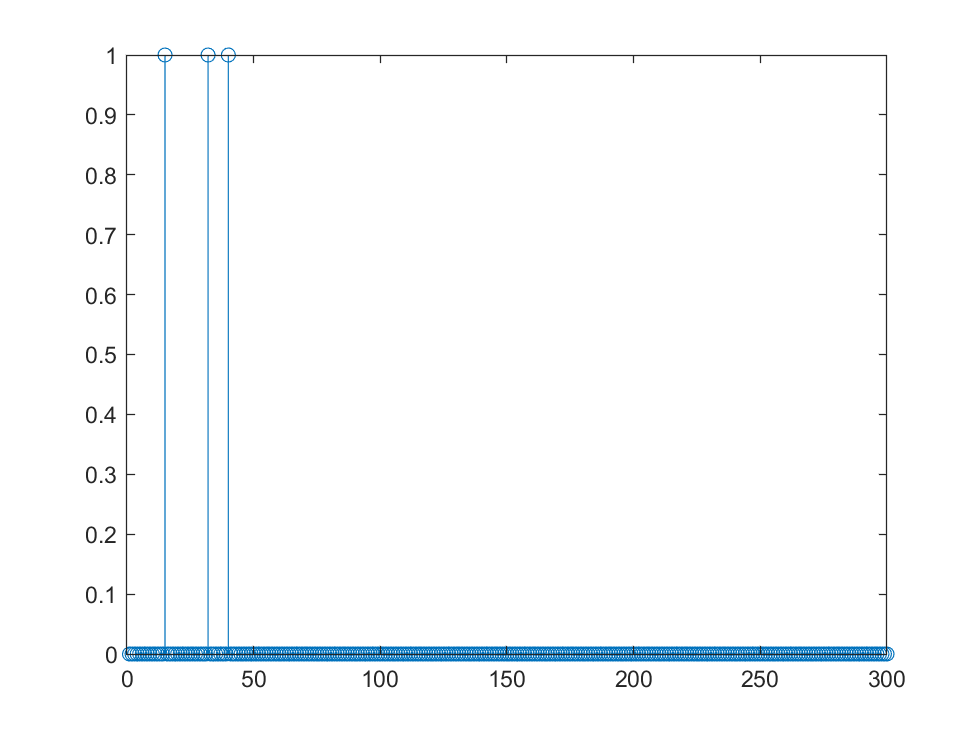

stem(trackBlinks.Data)

Signal derivative

Deviation of the signal from its running average

windowLength = 21;
sSmooth = movmean(s,windowLength);
figure;
plot((1:N).', s, (1:N).',sSmooth)
figure;
plot(s-sSmooth);
